syms x y z
J = jacobian([x^2-2*y, x+y+z, x-2*y+3*z], [x, y, z])

$$J = \left(\begin{array}{ccc} 2\,x & -2 & 0\\ 1 & 1 & 1\\ 1 & -2 & 3 \end{array}\right)$$

det(J)

$$ans = 10\,x+4$$

syms x y r theta
x = r*cos(theta);
y = r*sin(theta);
J = jacobian([x^2-2*y^2, 2*x^2-y^2], [r, theta])

$$J = \left(\begin{array}{cc} 2\,r\,{\cos\left(\theta \right)}^{2}-4\,r\,{\sin\left(\theta \right)}^{2} & -6\,r^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)\\ 4\,r\,{\cos\left(\theta \right)}^{2}-2\,r\,{\sin\left(\theta \right)}^{2} & -6\,r^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right) \end{array}\right)$$

d = det(J)

$$d = 12\,r^{3}\,{\cos\left(\theta \right)}^{3}\,\sin\left(\theta \right)+12\,r^{3}\,\cos\left(\theta \right)\,{\sin\left(\theta \right)}^{3}$$

simplify(d)

$$ans = 6\,r^{3}\,\sin\left(2\,\theta \right)$$

syms x y u v
x = u*(1-v)

$$x = -u\,\left(v-1\right)$$

y = u*v

$$y = u\,v$$

J = jacobian([x, y], [u,v])

$$J = \left(\begin{array}{cc} 1-v & -u\\ v & u \end{array}\right)$$

M = J * inv(J)

$$M = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

det(M)

$$ans = 1$$

syms x y
fun = @(x,y) 1./(sqrt(x+y).*(1+x+y).^2);
ymax = @(x) 1- x;
integral2(fun, 0, 1, 0, ymax)%prforms matrix like operation with function hence '.' needed

ans = 0.2854

syms y x
fun = @(x, y) y.*sin(x) + x.*cos(y);
integral2(fun, -pi, 2*pi, 0, pi)

ans = -9.8696

syms x y
fun = @(x, y) x.*(x.^2 + y.^2);
ymax = @(x) x.^2;
integral2(fun, 0, 5, 0, ymax)

ans = 1.8880e+04

syms r theta
fun = @(r, theta) r./(sqrt(r.*cos(theta)+r.*sin(theta)).*(1+r.*cos(theta)+r.*sin(theta).^2));
tmax = @(theta) 1./(sin(theta)+cos(theta));
integral2(fun, 0, pi/2, 0, tmax)

ans = 0.4811

syms x y z
fun = @(x, y, z) x + y + z;
integral3(fun, 0, 2, 0, 2, 0, 2)

ans = 24.0000

syms x k n pi
evalin(symengine, 'assume(k, Type::Integer)');%declare K as integer
a  = @(f, x, k, pi) int(f * cos(k*x)/pi, x, -pi, pi);%intrgral function wrt to x, b/w given limits for 'a'
b = @(f, x, k, pi) int(f*sin(k*x)/pi, x, -pi, pi);%intrgral function wrt to x, b/w given limits 'b'
f = x - x^2;
simplify(a(f, x, k, pi))

$$ans = -\frac{2\,\left(k^{2}\,\pi^{2}\,\sin\left(k\,\pi \right)-2\,\sin\left(k\,\pi \right)+2\,k\,\pi \,\cos\left(k\,\pi \right)\right)}{k^{3}\,\pi }$$

simplify(b(f, x, k, pi))

$$ans = \frac{2\,\left(\sin\left(k\,\pi \right)-k\,\pi \,\cos\left(k\,\pi \right)\right)}{k^{2}\,\pi }$$

fs =@(f, x, n, pi) a(f, x, 0, pi)/2 + symsum(a(f, x, k, pi) * cos(k * x) + b(f, x, k, pi) * sin(k * x), k, pi, n);
%create a fourier series function
pretty(fs(f, x, 3, pi))

  / /    3                                          \   /    3                          \ \
  | |  ---             2   2                        |   |  ---                          | |
  | |  \    cos(k x) (k  pi  #1 - 2 #1 + 2 k pi #2) |   |  \    sin(k x) (#1 - k pi #2) | |
  | |  /    --------------------------------------- | - |  /    ----------------------- | | 2
  | |  ---                      3                   |   |  ---              2           | |       2
  \ \ k = pi                   k                    /   \ k = pi           k            / /     pi
- ------------------------------------------------------------------------------------------- - ---
                                               pi                                                3

where

   #1 == sin(k pi)

   #2 == cos(k pi)




syms x k n l
evalin(symengine, 'assume(k, Type::Integer)');
a = @(f, x, k, l) int(f * cos(k * pi * x/l)/l, x, -l, l);
b = @(f, x, k, l) int(f * sin(k * pi * x/l)/l, x, -l, l);

f = abs(x);
a(f, x, k, 1)

$$ans = -\frac{2\,\left(2\,{\sin\left(\frac{k\,\pi }{2}\right)}^{2}-k\,\pi \,\sin\left(k\,\pi \right)\right)}{k^{2}\,\pi^{2}}$$

b(f, x, k, 1)

$$ans = 0$$

%f -> the function whose series is to be found
%x -> the independent variable of function x
%k -> the nth term of a or b
%l -> the limits of integration

fs = @(f, x, n, l) a(f, x, 0, l)/2 + symsum(a(f, x, k, l) * cos(k * pi * x/l) + b(f, x, k, l) * sin(k * pi * x/l), k, 1, n);
fs(f, x, 2, 1)

$$ans = \frac{\cos\left(2\,\pi \,x\right)\,\left(2\,\pi \,\sin\left(2\,\pi \right)-2\,{\sin\left(\pi \right)}^{2}\right)}{2\,\pi^{2}}-\frac{2\,\cos\left(\pi \,x\right)\,\left(2\,{\sin\left(\frac{\pi }{2}\right)}^{2}-\pi \,\sin\left(\pi \right)\right)}{\pi^{2}}+\frac{1}{2}$$

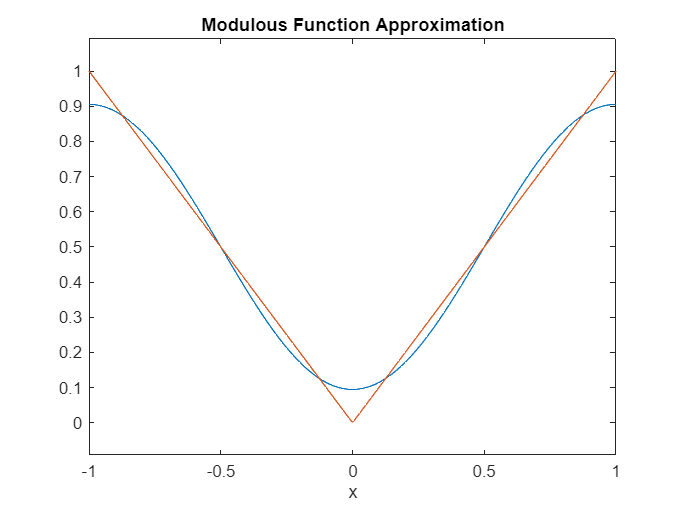


%plotting the graph
ezplot(fs(f, x, 1, 1), -1, 1)
hold on
ezplot(f, -1, 1)
hold off
title("Modulous Function Approximation")

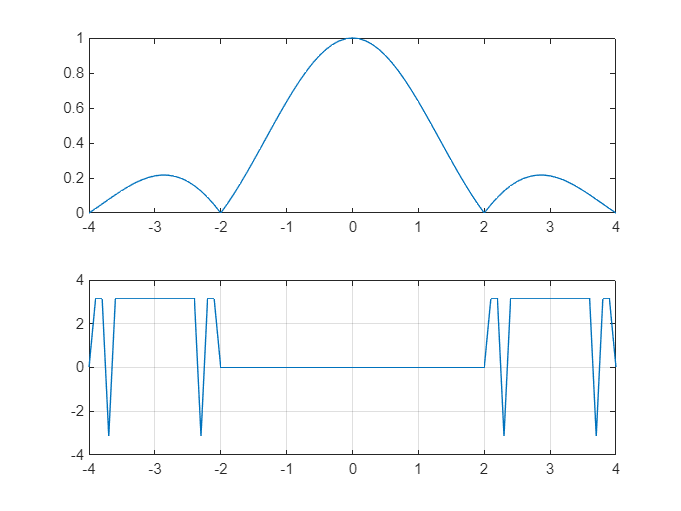

clf; clear all
syms t
f = -4:0.1:4;
F = int(1 * exp(-i*pi*f*t), t, -0.5, 0.5);
F1 = double(F);
subplot(211)
plot(f, abs(F1))
subplot(212)
plot(f, angle(F1))
grid on

syms t x
func = exp(-1*(t^2 + x^2))

$$func = {\mathrm{e}}^{-t^{2}-x^{2}}$$

fourier(func)

$$ans = \sqrt{\pi }\,{\mathrm{e}}^{-t^{2}-\frac{w^{2}}{4}}$$

syms t
func = t * exp(-t^2)

$$func = t\,{\mathrm{e}}^{-t^{2}}$$

fourier(func)

$$ans = -\frac{w\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{w^{2}}{4}}\,\mathrm{i}}{2}$$

syms omega
ifunc = exp(-(omega^2/4));
ifourier(ifunc)

$$ans = \frac{{\mathrm{e}}^{-x^{2}}}{\sqrt{\pi }}$$

syms w a
ifunc = exp(-(w^2 - a^2));
ifourier(ifunc)

$$ans = \frac{{\mathrm{e}}^{a^{2}-\frac{x^{2}}{4}}}{2\,\sqrt{\pi }}$$